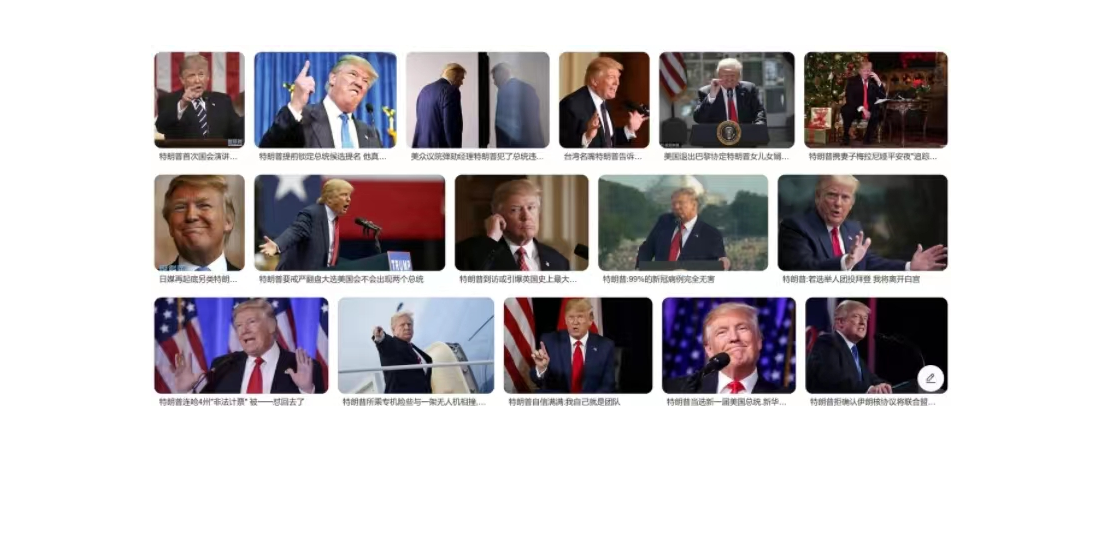

clear;
load v.mat;
img = imread('trump1.jpg');
[H,W,~] = size(img);
imshow(img);
img = double(img);
hold on;

% rectangle('Position',[0,0,30,30],'EdgeColor','r');

% 以20*20分块来进行扫描
step = 20;
ther = 0.1;
% 扫描第一遍
i = 1;
j = 1;
face_i = [];
face_j = [];
while i < H-step
    j = 1;
    while j < W-step
        block = img(i:i+step,j:j+step,:);
        u = get_u(block,4);
        if abs(u - v_2)<ther
            face_i = [face_i,i];
            face_j = [face_j,j];
        end
        j = j+step;
    end
    i = i+step;
end

% 扫描第二遍
i = step/2+1;
while i < H-step
    j = step/2+1;
    while j < W-step
        block = img(i:i+step,j:j+step,:);
        u = get_u(block,4);
        if abs(u - v_2)<ther
            face_i = [face_i,i];
            face_j = [face_j,j];
        end
        j = j+step;
    end
    i = i+step;
end

[~,p] = size(face_i);
for k = 1:1:p
    %     rectangle('Position',[face_j(k),face_i(k),step,step],'EdgeColor','r');
end

% 画大框框覆盖小框框
pic = zeros(H,W);
for k = 1:1:p
    pic(face_i(k),face_j(k))=1;
end
for i = step/2+1:step/2:H-step
    for j = step/2+1:step/2:W-step


        if pic(i,j)==1 &&  pic(i,j+step)==1
            pic(i,j+step/2)=1;
        end
        if pic(i,j)==1 &&  pic(i+step,j)==1
            pic(i+step/2,j)=1;
        end

        %         去除孤立点位
        if pic(i,j)==1 &&  pic(i+step/2,j)==0 &&  pic(i-step/2,j)==0 ...
                && pic(i,j+step/2)==0 &&  pic(i,j-step/2)==0
            pic(i,j)=0;
        end

    end
end

for i = 1+step/2:step/2:H-step/2
    for j = 1+step/2:step/2:W-step/2
        if pic(i,j)==1
            
            ii = i;
            jj = j;
            while ii >= 1 && jj >= 1 && ii <= H && jj <= W ...
                    && pic(ii+step/2,jj+step/2) == 1
                ii = ii + step/2;
                jj = jj + step/2;
            end
            for m = min(i,ii):step/2:max(i,ii)
                for n = min(j,jj):step/2:max(j,jj)
                    pic(m,n)=1;
                end
            end
            
            ii = i;
            jj = j;
            while ii >= 1 && jj >= 1 && ii <= H && jj <= W ...
                    && jj >= step/2+1 && pic(ii+step/2,jj-step/2) == 1 
                ii = ii + step/2;
                jj = jj - step/2;
            end
            for m = min(i,ii):step/2:max(i,ii)
                for n = min(j,jj):step/2:max(j,jj)
                    pic(m,n)=1;
                end
            end
            
            ii = i;
            jj = j;
            while ii >= 1 && jj >= 1 && ii <= H && jj <= W ...
                     && jj >= step/2+1 && ii > step/2+1 && pic(ii-step/2,jj-step/2) == 1
                ii = ii - step/2;
                jj = jj - step/2;
            end
            for m = min(i,ii):step/2:max(i,ii)
                for n = min(j,jj):step/2:max(j,jj)
                    pic(m,n)=1;
                end
            end
            
            ii = i;
            jj = j;
            while ii >= 1 && jj >= 1 && ii <= H && jj <= W ...
                    && ii > step/2+1 && pic(ii-step/2,jj+step/2) == 1 
                ii = ii - step/2;
                jj = jj + step/2;
            end
            for m = min(i,ii):step/2:max(i,ii)
                for n = min(j,jj):step/2:max(j,jj)
                    pic(m,n)=1;
                end
            end
        end
    end
end

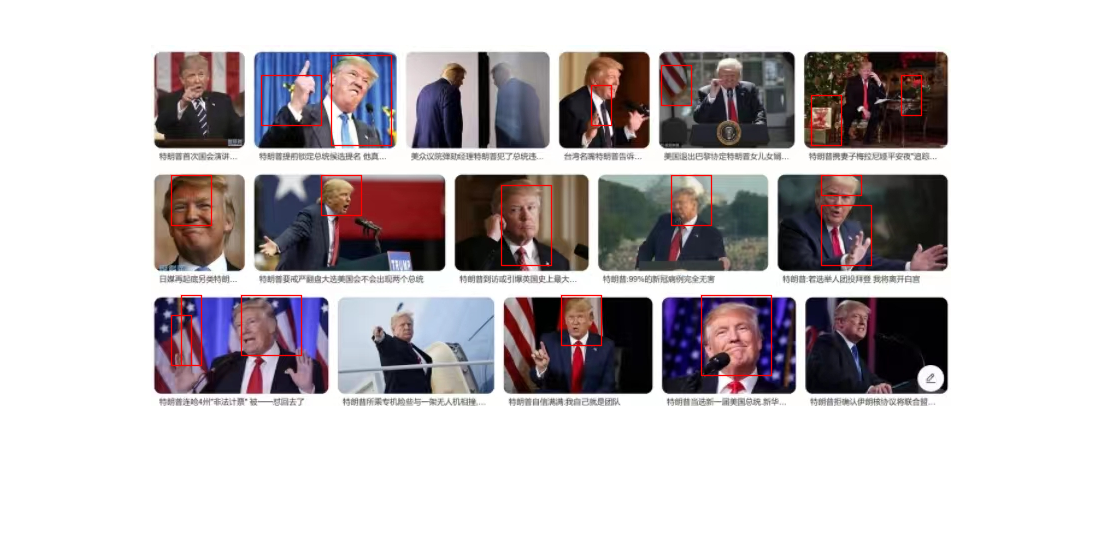

figure;
imshow(uint8(img));
hold on;

for i = 1+step/2:step/2:H-step/2
    for j = 1+step/2:step/2:W-step/2
        if pic(i,j)==1
            ii = i;
            jj = j;
            while pic(ii,j) == 1
                ii = ii + step/2;
            end
            while pic(i,jj) == 1
                jj = jj + step/2;
            end
            rectangle('Position',[j,i,jj-j+step/2,ii-i+step/2],'EdgeColor','r');
            for m = i:step/2:ii-step/2
                for n = j:step/2:jj-step/2
                    pic(m,n)=0;
                end
            end
        end
    end
end